# Solve DAE for a simple Pendulum

Example from documentation:

- [https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html](https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html)

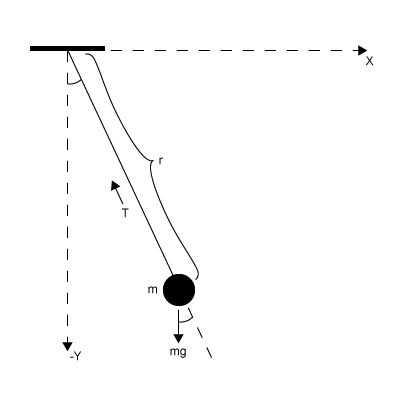

State variables

- Horizontal position of pendulum $x\left(t\right)$

- Vertical position of pendulum $y\left(t\right)$

- Force preventing pendulum from flying away $T\left(t\right)$

Parameters

- Pendulum mass $m$

- Pendulum length $r$

- Gravitational constant $g$

DAE system of equations


$$\begin{array}{l}
m\frac{d^{2\;} x}{{\textrm{dt}}^{2\;} }=T\left(t\right)\frac{x\left(t\right)}{r\;}\\
m\frac{d^{2\;} y}{{\textrm{dt}}^{2\;} }=T\left(t\right)\frac{y\left(t\right)}{r\;}-\textrm{mg}\\
x^{2\;} \left(t\right)+y^{2\;} \left(t\right)=r^2 
\end{array}$$


clear variables

syms x(t) y(t) T(t) m r g

eqn1 = m*diff(x(t), 2) == T(t)/r*x(t)

$$eqn1 = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{T\left(t\right)\,x\left(t\right)}{r}$$

eqn2 = m*diff(y(t), 2) == T(t)/r*y(t) - m*g

$$eqn2 = m\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{T\left(t\right)\,y\left(t\right)}{r}-g\,m$$

eqn3 = x(t)^2 + y(t)^2 == r^2

$$eqn3 = {x\left(t\right)}^{2}+{y\left(t\right)}^{2}=r^{2}$$

eqns = [eqn1 eqn2 eqn3];
vars = [x(t); y(t); T(t)];
origVars = length(vars)

origVars = 3

Check Incidence of Variables

M = incidenceMatrix(eqns, vars)

M =      1     0     1
     0     1     1
     1     1     0


Reduce Differential Order

[eqns, vars] = reduceDifferentialOrder(eqns, vars)

$$eqns = \left(\begin{array}{c} m\,\frac{\partial }{\partial t}\mathrm{Dxt}\left(t\right)-\frac{T\left(t\right)\,x\left(t\right)}{r}\\ g\,m+m\,\frac{\partial }{\partial t}\mathrm{Dyt}\left(t\right)-\frac{T\left(t\right)\,y\left(t\right)}{r}\\ -r^{2}+{x\left(t\right)}^{2}+{y\left(t\right)}^{2}\\ \mathrm{Dxt}\left(t\right)-\frac{\partial }{\partial t}x\left(t\right)\\ \mathrm{Dyt}\left(t\right)-\frac{\partial }{\partial t}y\left(t\right) \end{array}\right)$$

$$vars = \left(\begin{array}{c} x\left(t\right)\\ y\left(t\right)\\ T\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dyt}\left(t\right) \end{array}\right)$$

Check Differential Index of System

if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")
    % Reduce Differential Index with reduceDAEIndex
    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)
    % Eliminate redundant equations and variables
    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)
    % Check the differential index of the new system
    assert(isLowIndexDAE(DAEs, DAEvars))
else
    DAEs = eqns;
    DAEvars = vars;
end

Reducing Differential Index...


$$DAEs = \left(\begin{array}{c} m\,\mathrm{Dxtt}\left(t\right)-\frac{T\left(t\right)\,x\left(t\right)}{r}\\ g\,m+m\,\mathrm{Dytt}\left(t\right)-\frac{T\left(t\right)\,y\left(t\right)}{r}\\ -r^{2}+{x\left(t\right)}^{2}+{y\left(t\right)}^{2}\\ \mathrm{Dxt}\left(t\right)-{\mathrm{Dxt}}_{7}\left(t\right)\\ \mathrm{Dyt}\left(t\right)-{\mathrm{Dyt}}_{7}\left(t\right)\\ 2\,{\mathrm{Dxt}}_{7}\left(t\right)\,x\left(t\right)+2\,{\mathrm{Dyt}}_{7}\left(t\right)\,y\left(t\right)\\ 2\,y\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{Dyt}}_{7}\left(t\right)+2\,{{\mathrm{Dxt}}_{7}\left(t\right)}^{2}+2\,{{\mathrm{Dyt}}_{7}\left(t\right)}^{2}+2\,\mathrm{Dxt7t}\left(t\right)\,x\left(t\right)\\ \mathrm{Dxtt}\left(t\right)-\mathrm{Dxt7t}\left(t\right)\\ \mathrm{Dytt}\left(t\right)-\frac{\partial }{\partial t}{\mathrm{Dyt}}_{7}\left(t\right)\\ {\mathrm{Dyt}}_{7}\left(t\right)-\frac{\partial }{\partial t}y\left(t\right) \end{array}\right)$$

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ y\left(t\right)\\ T\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dyt}\left(t\right)\\ \mathrm{Dytt}\left(t\right)\\ \mathrm{Dxtt}\left(t\right)\\ {\mathrm{Dxt}}_{7}\left(t\right)\\ {\mathrm{Dyt}}_{7}\left(t\right)\\ \mathrm{Dxt7t}\left(t\right) \end{array}\right)$$

$$DAEs = \left(\begin{array}{c} -\frac{T\left(t\right)\,x\left(t\right)-m\,r\,\mathrm{Dxtt}\left(t\right)}{r}\\ \frac{g\,m\,r-T\left(t\right)\,y\left(t\right)+m\,r\,\mathrm{Dytt}\left(t\right)}{r}\\ -r^{2}+{x\left(t\right)}^{2}+{y\left(t\right)}^{2}\\ 2\,\mathrm{Dxt}\left(t\right)\,x\left(t\right)+2\,\mathrm{Dyt}\left(t\right)\,y\left(t\right)\\ 2\,{\mathrm{Dxt}\left(t\right)}^{2}+2\,{\mathrm{Dyt}\left(t\right)}^{2}+2\,\mathrm{Dxtt}\left(t\right)\,x\left(t\right)+2\,\mathrm{Dytt}\left(t\right)\,y\left(t\right)\\ \mathrm{Dytt}\left(t\right)-\frac{\partial }{\partial t}\mathrm{Dyt}\left(t\right)\\ \mathrm{Dyt}\left(t\right)-\frac{\partial }{\partial t}y\left(t\right) \end{array}\right)$$

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ y\left(t\right)\\ T\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dyt}\left(t\right)\\ \mathrm{Dytt}\left(t\right)\\ \mathrm{Dxtt}\left(t\right) \end{array}\right)$$

### Convert DAE system to MATLAB function

pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

$$extraParams = \left(\begin{array}{ccc} g & m & r \end{array}\right)$$

Create the function handle

f = daeFunction(DAEs, DAEvars, g, m, r);

### Set parameter values

g = 9.81;
m = 1;
r = 1;

Create function for ode15i

F = @(t, Y, YP) f(t, Y, YP, g, m, r);

### Find initial condition

DAEvars

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ y\left(t\right)\\ T\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dyt}\left(t\right)\\ \mathrm{Dytt}\left(t\right)\\ \mathrm{Dxtt}\left(t\right) \end{array}\right)$$

Note that `Dxt(t)`, `Dxtt(t)`, ... etc. are the first and second derivatives of `x(t)`.

Provide an estimate of the initial condition

% Variables
x0est = [r*sin(pi/6); -r*cos(pi/6); 0; 0; 0; 0; 0];
% Their derivatives
xp0est = zeros(7, 1);

Set tolerances and do numerical search.

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[x0, xp0] = decic(F, 0, x0est, [], xp0est, [], opt)

x0 =     0.4771
   -0.8788
   -8.6214
         0
    0.0000
   -2.2333
   -4.1135


xp0 =          0
    0.0000
         0
         0
   -2.2333
         0
         0


### Solve DAEs Using ode15i

[tSol, xSol] = ode15i(F, [0 0.5], x0, xp0, opt);

Plot solution

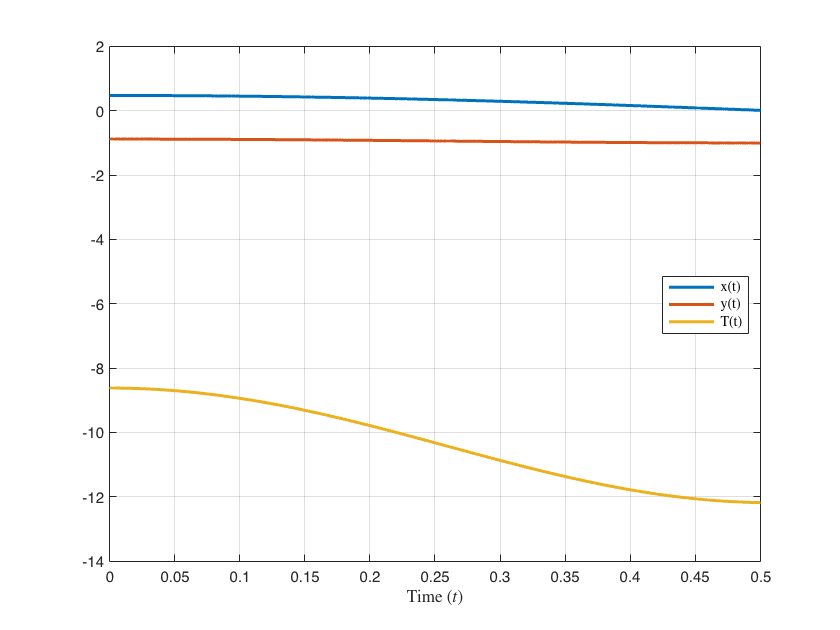

plot(tSol, xSol(:, 1:origVars), 'LineWidth', 2)
xlabel("Time ($t$)", 'Interpreter', 'latex')
labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);
legend(labels, 'Location', 'Best', 'Interpreter', 'latex')
grid on